clear
clf
load bana800-77.mat
plotTrack(portx, porty, ver, v1);
ylim([-100 900])
xlim([-100 900])
c = 0.25; % kg/m
g = 9.82; % m/s^2
km = 2000; % m/s
alpha = 0;
tspan = [0,800];
xybv = [0, 15, 425, -10]; % 4 inputs?
n = 100;
%[t,y] = minRK2(@mp3Funk, tspan, xybv, n)
[t,y_ode]=ode45(@mp3Funk,tspan,xybv)

t =          0
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0001
    0.0001
    0.0002


y_ode = 	1.0e+04 *

         0    0.0015    0.0425   -0.0010
    0.0000    0.0015    0.0425   -0.0010
    0.0000    0.0015    0.0425   -0.0010
    0.0000    0.0015    0.0425   -0.0010
    0.0000    0.0015    0.0425   -0.0010
    0.0000    0.0015    0.0425   -0.0010
    0.0000    0.0015    0.0425   -0.0010
    0.0000    0.0015    0.0425   -0.0010
    0.0000    0.0015    0.0425   -0.0010
    0.0000    0.0015    0.0425   -0.0010


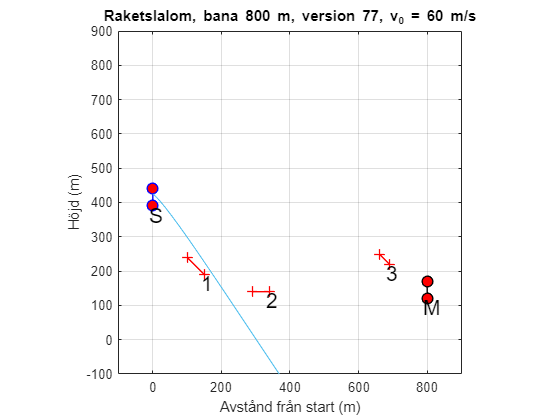

%x = y_ode(:,1);
%y = y_ode(:,3);
hold on
plot(y_ode(:,1), y_ode(:,3))

%plot(t, y_ode(:,3))

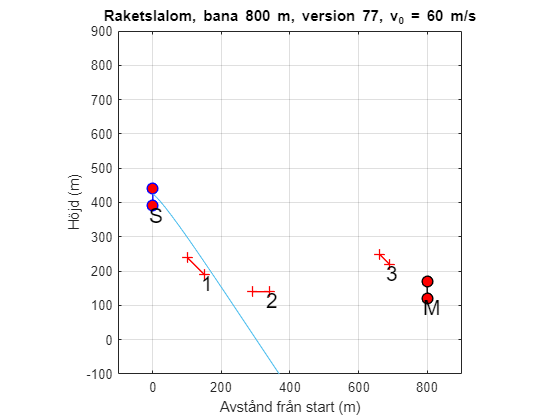

hold on

clear
clf
x = linspace(1,800,800)

x =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


% 400 + −2,18x + 4,89×10^−03x^2 + −2,05×10^−06x^3 + −1,46×10^−09x^4
y = 400 - 2.18 * x + 4.89 * 10^-3 * x.^2 - 2.05 * 10^-6 * x.^3 - 1.46*10^-9 * x.^4

y =   397.8249  395.6595  393.5040  391.3581  389.2220  387.0956  384.9789  382.8719  380.7746  378.6869  376.6089  374.5406  372.4819  370.4328  368.3933  366.3633  364.3430  362.3323  360.3310  358.3394  356.3572  354.3846  352.4215  350.4678  348.5236  346.5889  344.6637  342.7479  340.8415  338.9445  337.0569  335.1787  333.3098  331.4503  329.6002  327.7593  325.9278  324.1056  322.2927  320.4891  318.6947  316.9095  315.1336  313.3669  311.6095  309.8612  308.1220  306.3921  304.6713  302.9596


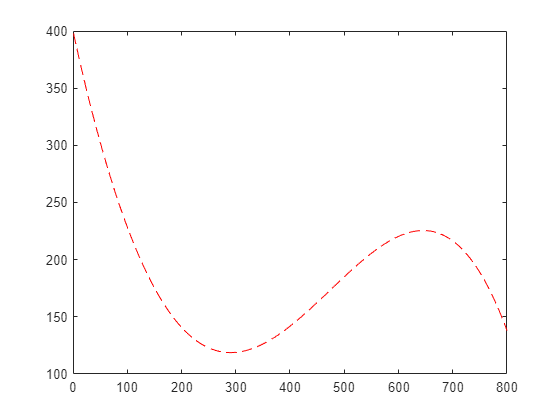

plot(x, y, '--r')
hold off

% deriv
% -2.18 + 0.00978 x - 6.15×10^-6 x.^2 - 5.84×10^-9 x.^3
yderiv = -2.18 + 0.00978 * x - 6.15 * 10^-6 * x.^2 - 5.84 * 10^-9 * x.^3

yderiv =    -2.1702   -2.1605   -2.1507   -2.1410   -2.1313   -2.1215   -2.1118   -2.1022   -2.0925   -2.0828   -2.0732   -2.0635   -2.0539   -2.0443   -2.0347   -2.0251   -2.0155   -2.0060   -1.9964   -1.9869   -1.9774   -1.9679   -1.9584   -1.9489   -1.9394   -1.9300   -1.9205   -1.9111   -1.9017   -1.8923   -1.8829   -1.8735   -1.8642   -1.8548   -1.8455   -1.8362   -1.8269   -1.8176   -1.8083   -1.7990   -1.7898   -1.7805   -1.7713   -1.7621   -1.7529   -1.7437   -1.7345   -1.7254   -1.7162   -1.7071


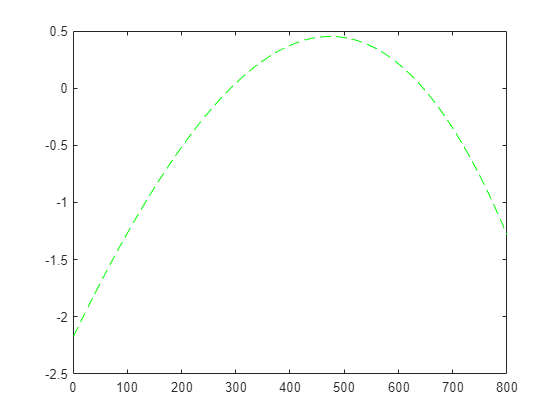

plot(x, yderiv, '--g')
hold on